## LQR: Cost and Effective Force

Linear Quadratic Regulation acheives its regulation by modifying the force that is applied to the system. After each time step, the force is adjusted through the internal parameter $u$. The amount of adjustment is determined by an internal $K$ matrix, computed at the start of the simulation. $K$ is computed such that it minimizes a cost function. Cost is essentially a measure of energy expenditure.

The figure below shows the incremental cost or energy expenditure computed at each iteration step. It drops by two orders of magnitude after the first few iterations, and then converges to zero. 

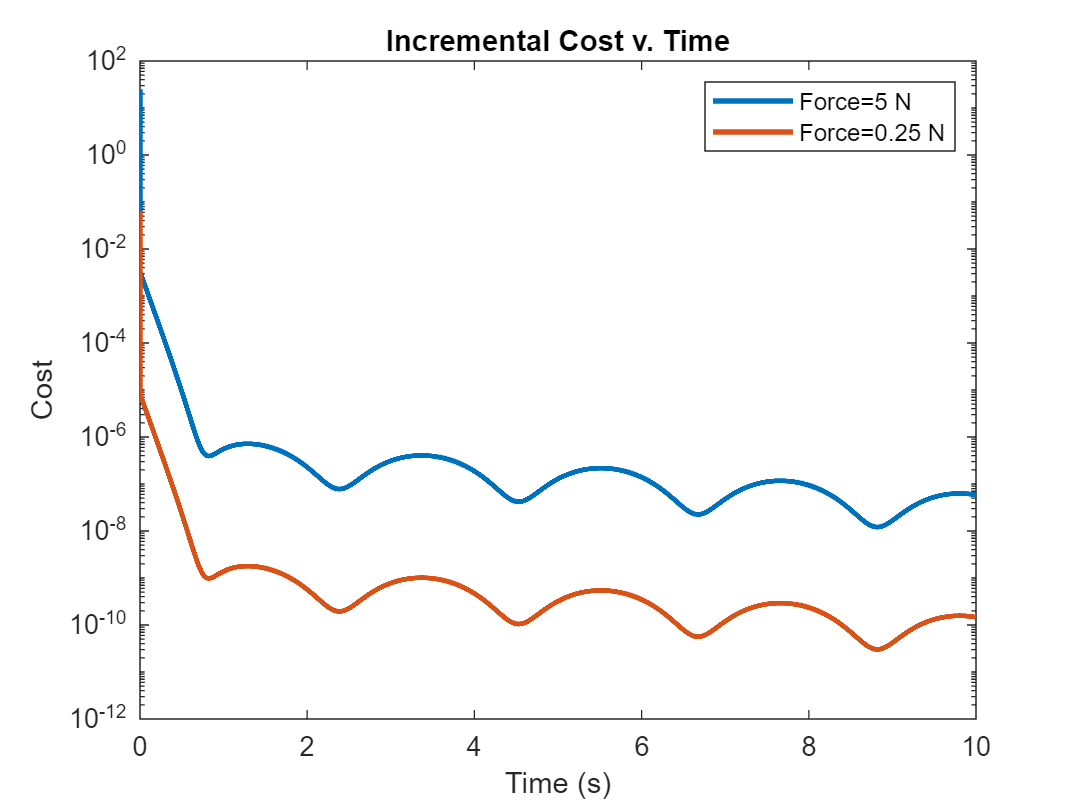

time_t = [0:0.001:10];

IP = InvertedPendulum();

V0 = [0;0; 0;0]; % Initial position

%non-default LQR 'Q' matrix that includes only X and phi:
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];

% create the inverted pendulum
IP = InvertedPendulum();

%simulate and plot the 5 Newton force
sr = IP.euler_method(V0, 5, time=time_t, lqr=true, ...
    Q=Q, description='Force=5 N');
sr.plotdC(cumulative=false);

%simulate and plot the 0.25 Newton force
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q, description='Force=0.25 N');
hold on
sr2.plotdC(cumulative=false)
hold off

legend()

The cumulative cost, that is the total energy expenditure over the time frame of the solution, rises steeply at first, then levels out. In the scale of the graphs below, each major tick is $10^{-3}$ seconds which is the timestep of the simulation. The graphs show, therefore, that most of the LQR impact is within the first few  time steps.

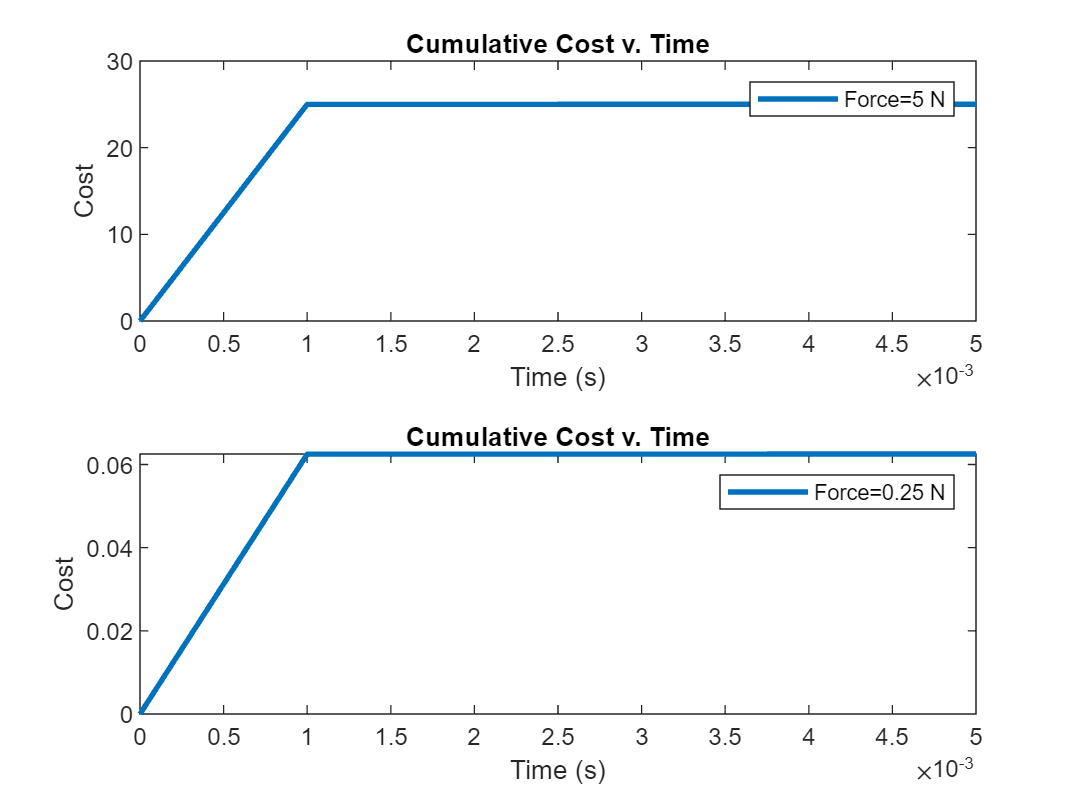

clf
tiledlayout(2,1)
nexttile
sr.plotdC(cumulative=true)
xlim([0 0.005])
legend
nexttile
sr2.plotdC(cumulative=true)
xlim([0 0.005])
legend

LQR works by adjusting the force applied to the system after each iteration. The internal parameter $u$ is the effective force. The figure below shows $u$ for the two simulations over the first few timesteps. LQR quickly reduces $u$ to near-zero which means that the lateral force applied to the cart lasts for only a few milliseconds. The removal of force, then allows the cart to bleed off energy and return to equilibrium.

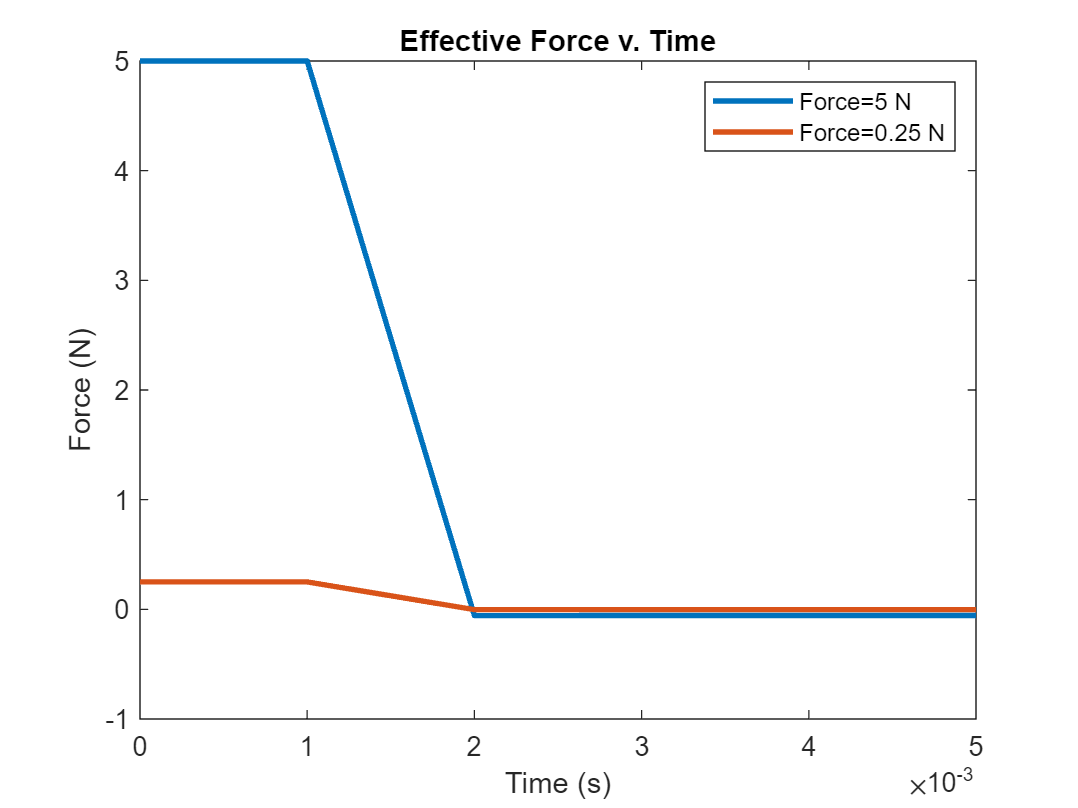

clf
sr.plotu()
hold on
sr2.plotu()
hold off
xlim([0  0.005])
legend